1) Suppose we have some good data centered around 12, as well as some bad data mixed in that is given to us:

     A1) Setting up the data

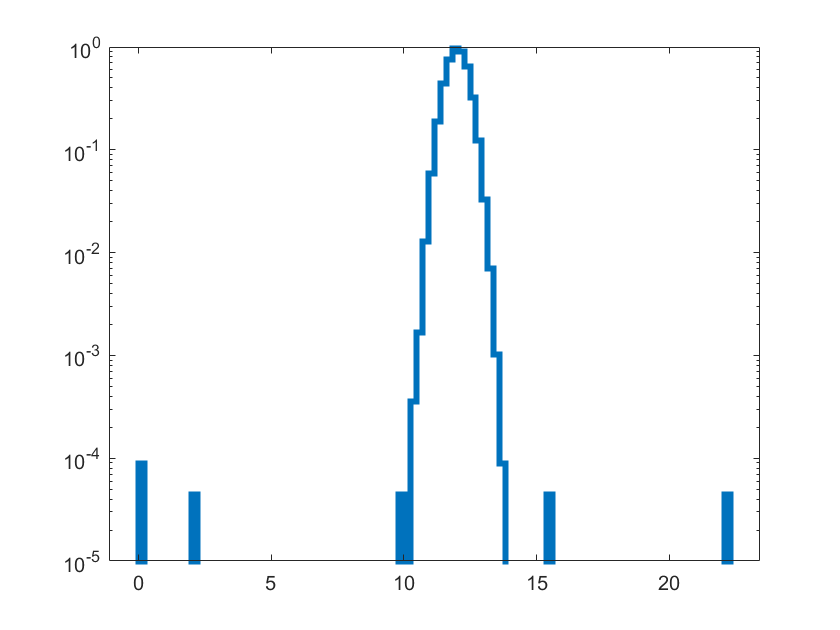

mean = 12;
stdev = 0.4;
trials = 100000;
temps = random('Normal', mean, stdev, [1,trials]);   %random 'good' data
badData = [10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7]; %copied from lab instructions
temps = [temps, badData]; %add in bad data
histogram(temps,100,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
set(gca,'YScale','log')

xlabel('Temperature (Kelvin)')
ylabel('Probability')
title("Temperature measurement probability")

A2) To find the bad data points, I will ask the statistical question of what is the probability for a random data point, that its measured value is explained by the true background distribution of temperatures and not due to a bad data point. I chose this question, because it needs to be asked for each and every point to search through them for any bad data points. I will need arbitrarily select a sigma value where I accept any data within it as good, and outside as bad. 

A3) Given a random data point $d$, what is the probability that the background gaussian distribution centered at 12 with a sigma of 0.4 would produce a measuremnt as extreeme or more than $d$? for $d<\textrm{mean}:\int_0^d P\left(d\right)d\;d$ and $d>\textrm{mean}:\int_d^{\infty } P\left(d\right)d\;d$ 

A4) From looking at the plots 

cutoffSigma = 5;        %Maximum sigma value allowed for good data points
outliers = [];%zeros(size(temps));
sigma = 0;
finalTemps = zeros(size(temps));    %preallocate final temps for speed
for i = 1:length(temps)
    sigma = (mean - temps(i)) / stdev;  %works for normal distribution
    if(abs(sigma) > cutoffSigma)  %If bad data
        outliers(end+1) = temps(i);
    else                          %If good data
        finalTemps(i) = temps(i);
    end
end
sigma

sigma = -1.7500

%delete zeros from final temps which were added during memory allocation
finalTemps = nonzeros(finalTemps);
%outliers = nonzeros(outliers');
outliers

outliers =     2.1000         0         0   15.6000   22.3000


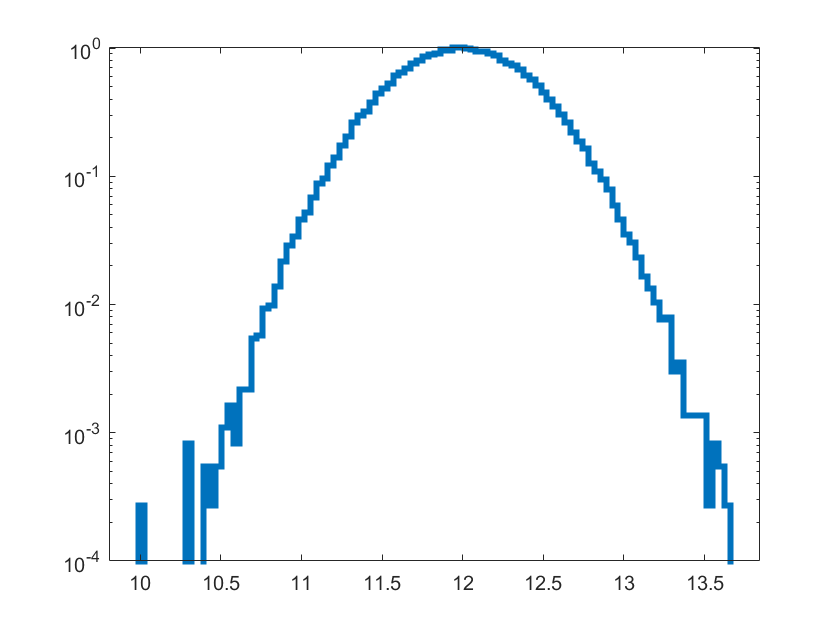

histogram(finalTemps,100,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
set(gca,'YScale','log')

xlabel('Temperature (Kelvin)')
ylabel('Probability')
title("5-sigma + outliers removed")

For a value of 5 sigma, only 5/8 bad data points were detected, while no good data points were detected as bad data points. On this plot, the bad data points of 10, and 10.3 still seem to be distinct from the main distribution of good data, while the 12.7 bad data point is likely impossible to detect since it lies in the middle of all the good data.

Below is the same code with a critical sigma of 4.2 instead of 5 to filter out some more of the bad data:

cutoffSigma = 4.2;        %Maximum sigma value allowed for good data points
outliers = [];%zeros(size(temps));
sigma = 0;
finalTemps = zeros(size(temps));    %preallocate final temps for speed
for i = 1:length(temps)
    sigma = (mean - temps(i)) / stdev;  %works for normal distribution
    if(abs(sigma) > cutoffSigma)  %If bad data
        outliers(end+1) = temps(i);
    else                          %If good data
        finalTemps(i) = temps(i);
    end
end
sigma

sigma = -1.7500

%delete zeros from final temps which were added during memory allocation
finalTemps = nonzeros(finalTemps);
%outliers = nonzeros(outliers');
outliers

outliers =    10.3014   10.0000   10.3000    2.1000         0         0   15.6000   22.3000


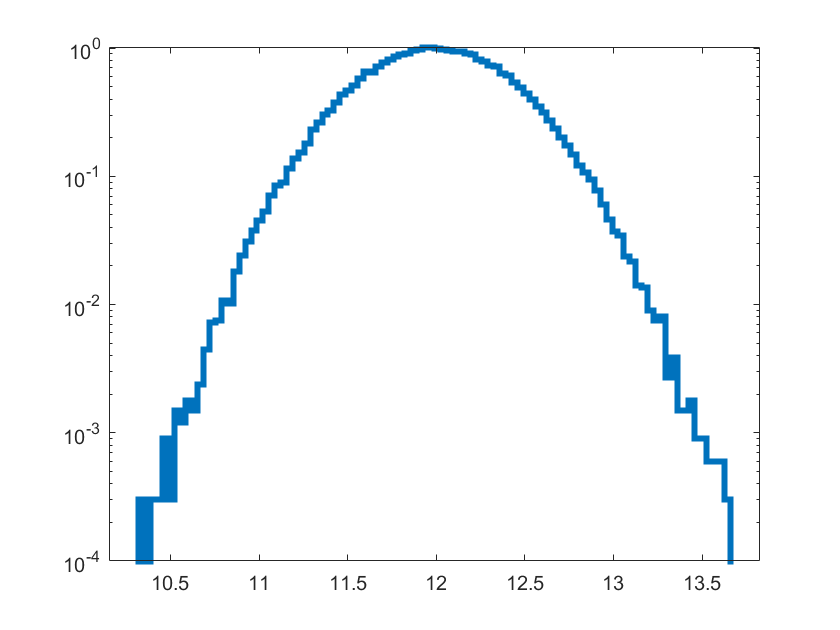

histogram(finalTemps,100,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
set(gca,'YScale','log')

xlabel('Temperature (Kelvin)')
ylabel('Probability')
title("4.2-sigma + outliers removed")

Now this algorith detected both the 10 and 10.3 bad data points while getting a few false positives. Since there is a large number of good data points that are more extreme than 12.7, the number of data points that would need to be discarded to exclude a bad data point of this size is very large, and I believe that it is better to not detect this bad data point than to discard thousands of good data points. This is a subjective decision, as depending on the experiment, even having one bad data point could possibly ruin an experiment, so tightening the allowable sigma to below 2 or using other methods may be necessary. Below is the truth table for this algorithm:

B) The expected number of omissions of good data is proportional to the statistical threshold chosen for this algorithm, since  a looser threshold will remove fewer good points as well as bad points, while a tighter threshold will remove more bad points but also remove more false positives. This quantity of false positives does have an expected value equal to the probability of any single randomly generated value being outside the threshold times the number of trials. The expected number of false positives for a threshold of 4.2 sigma  and 100k trials is calculated below:

sigma = [3, 4.2, 5, 10];
trials = 100000;
probability = normcdf(sigma, 'upper');    
expectedFalsePositives = trials * probability

expectedFalsePositives =   134.9898    1.3346    0.0287    0.0000


The expected number of false positives is this roughly 2.67 for a threshold sigma of 4.2, and you can see the expected false positives for 3, 4.2, 5, and 10 sigma thresholds calculated above.

C) There are mistakes of commission where bad data is allowed to pass through the above algorithm, since the bad 12.7 measurement was deemed good by the algorithm. This specific one is avoidable by choosing a very tight threshold with a sigma of about 1.5, but this would eliminate a large amount of good data to detect the bad data point. 

2) If we are looking for an asteroid in the sky, and we observe that it has moved by a distance $\Delta x$ between 2 images, there is some chance that this was not really an asteriod and the movement was simply due to a stationary object randomly appearing in a slightly different location in the two images. If the random displacement of stationary objects in the night sky between images can be represented by a 2-D gaussian with a 1 arcsecond RMS, then we can find the probability that some displacement could be explained by a stationary object randomly appearing in slightly different locatios.

2.1) We want to ask the statistical question of what is the distance $d$ where the probability of a stationary object moving this distance between two images is equal to a 5-sigma probability.

2.2) The distance between two points in 2-D space where $x,y$ are the coordiantes is given as $d=\sqrt{x^2 +y^2 }$, therefore the 2-D gaussian probaility of finding a stationary object a distance r away can be written as $P\left(d\right)=\sqrt{X^2 \hat{x} +Y^2 \hat{y} \;}$. From looking up relations to the normal distribution online, I found that taking the euclidean norm of two normal distributions like this yeilds a rayleigh distribution, so $P\left(d\right)$would be a rayleigh distribution where d is the distance, and since the gaussian distributions are standard normal distributions, the rayleigh distribution will be a standard rayleigh distribution where $\sigma =1$. The question now simplifies to one distribution instead of a 2-D distribution, and we can easily solve for d with the following code:

2.3) 

fiveSigma = normcdf(5);
d = raylinv(fiveSigma)

d = 5.4891

This gives us a distance of about 5.49 arcseconds, so if there were two subsequent images where an object moved about 5.5 arcseconds, this would be a '5 sigma' observation, and larger distances would yeild only increasingly significant results.

3) The moon and sun both block cosmic rays from hitting the earth, so they both cast a shadow of cosmic rays that can be detected from earth. 

3.1) Suppose we observe 6800 cosmic rays from the direction of the moon for 8 hours a night and for 15 days, whereas typically we detect 1 cosmic ray for miniute in a moon-sized patch of the sky. To find the significance of the moon shadow, we can ask the question, given a background distribution of 1 cosmic ray per minute, what is the probability that a measurement of 6800 rays over 15*8 hours can be explained by the background cosmic ray distribution?

3.2) Since cosmic rays are discrete events, the distribution describing their probability is lkely a poisson distribution. This poisson distribution would have a lambda of 1 for a time interval of 1 minute as given by the scenario. In the 15 days, there are $15*8*60=7200$ minutes. To find the probability distribution function for how many cosmic rays we would expect to see over a period of 7200 minutes, we must convolve the poission distribution 7200 times; knowing that the convolution of poisson distributions is simply a poisson distribution with a lambda equal to the sum of the lambdas of the individual summands. Therefore, the pdf for the entire period would be a poisson distribution with lambda equal to 7200. Since the measured value is less than the expected value, the integral to calculate the probability of this measurement or more extreeme is as follows: $\sum_0^{6800} \textrm{Poisspdf}\left(x,\lambda =7200\right)=\sum_{n\;=\;0}^{6800} \frac{{7200}^n e^{-7200} }{n!}$

pval = poisscdf(6800, 7200)

pval = 1.0133e-06

sigma = abs(norminv(pval))

sigma = 4.7507

This measurement of the shadow of the moon in terms of cosmic rays has a significance of about 4.75-sigma, slightly below the 5-sigma threshold for a discovery in physics. Since this result is close to being significant, continuing to run the experiment for some more days could possibly bring it past the 5-sigma standard for significance, or it could also regress to the mean if the observation really was simply due to random chance and not a real shadow.  